load 'C:\class\coursefiles\mlbe\gasoline\gPrices'

% ctry = inputdlg('Please enter a country: ');
% 
% idx = strcmpi(ctry, country)

% if any(idx)
%     disp(country(idx))
% else
%     error('no country by that name in data')
% end

badname = true;

while badname
    ctry = inputdlg('Please enter a country: ')
    idx = strcmpi(ctry, country)
    
    badname = ~any(idx);
    
    if badname
        waitfor(errordlg(['No country "', ctry{1},'" in data']))
    end % if
    
end % while

idx =    0   0   0   0   0   0   0   0   0   0


idx =    0   0   1   0   0   0   0   0   0   0



ctryPrice = Prices(:,idx);
othersPrice = Prices(:,~idx);
othersName = country(~idx);

Slope = zeros(size(othersName));    % pre allocate memory

for ii = 1 : length(othersName)
    c = polyfit(ctryPrice, othersPrice(:,ii),1);
    Slope(ii) = c(1);
    legabv{ii} = [ctry{1}, ' vs ', othersName{ii}];
    fits(:,ii) = c(2) + c(1)*ctryPrice;
end

Slope

Slope =     0.6935    0.6373    1.1991    0.9344    0.4621    0.2476    0.9137    1.1382    0.5443


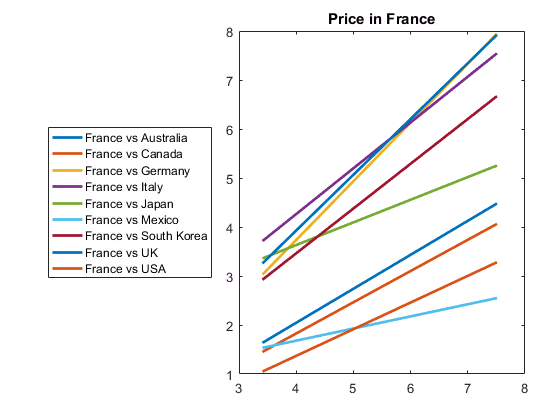


plot(ctryPrice, fits, 'LineWidth', 2)
title(['Price in ', ctry{1}])
legend(legabv,'Location','westoutside')

size(Slope)

ans =      1     9


size(Slope,2)

ans = 9

length(Slope)

ans = 9

numel(Slope)

ans = 9

idx = menu('Select a country:', country)

idx = 0

ctry = country{idx}

Cell contents indices must be greater than 0

%ctry = input('Enter a country: ','s');